**Submitted By**

**Hridya Divakaran : V00970167**

**Sanjana Arora : V00966221**

clear;
clc;

Loading the Exercise 5 data

a = load("Ex5_data.mat")

a = struct with fields:
            C: [15055×3 double]
           RA: [171235×3 double]
         RABC: [7343×3 double]
        RABCD: [1226×3 double]
           RB: [67133×3 double]
           RC: [118336×3 double]
           RD: [99456×3 double]
        cov_A: [3×3 double]
        cov_B: [3×3 double]
        cov_C: [3×3 double]
        cov_D: [3×3 double]
        cov_E: [3×3 double]
        dataA: [750000×3 double]
        dataB: [190000×3 double]
        dataC: [45000×3 double]
        dataD: [12000×3 double]
        dataE: [3000×3 double]
    dimension: 3
            j: 750000
       mean_A: [0 0 0]
       mean_B: [-0.7245 -0.1401 0.3956]
       mean_C: [-0.9420 0.0647 0.6022]
       mean_D: [-0.7793 -0.4620 0.3091]
       mean_E: [-0.2321 -0.0983 0.0907]
            r: 3.9510


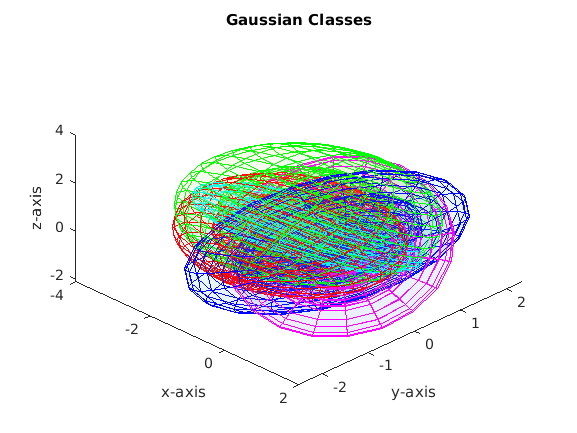


class_A = a.dataA;
class_B = a.dataB;
class_C = a.dataC;
class_D = a.dataD;
class_E = a.dataE;


figure
hold on
ellipsoid_plot(a.mean_A',a.cov_A,[1 0 1])
ellipsoid_plot(a.mean_B',a.cov_B,[0 1 1])
ellipsoid_plot(a.mean_C',a.cov_C,[0 1 0])
ellipsoid_plot(a.mean_D',a.cov_D,[1 0 0])
ellipsoid_plot(a.mean_E',a.cov_E,[0 0 1])
view([45, 45]);
title('Gaussian Classes');
xlabel('x-axis');
ylabel('y-axis');
zlabel('z-axis');
hold off

**Q2. Construct randomly (uniformly) selected training and test data set from the composite of your constructed 5 class data sets, where the training data should constitute 10% of the overall data and the test data on the remaining 90% of the data. Record the number of training data samples for each training set class as well as the exact indexes of the training and testing data samples.**

% Splitting the data into training (10%) and testing (90%) using the
% function defined below

[class_A_training, class_A_testing] = train_validation_split(class_A);
[class_B_training, class_B_testing] = train_validation_split(class_B);
[class_C_training, class_C_testing] = train_validation_split(class_C);
[class_D_training, class_D_testing] = train_validation_split(class_D);
[class_E_training, class_E_testing] = train_validation_split(class_E);


training_data = [class_A_training; class_B_training; class_C_training; class_D_training; class_E_training];
testing_data = [class_A_testing; class_B_testing; class_C_testing; class_D_testing; class_E_testing];

% One hot encoding the class labels
trueclassindices = [ 1 2 3 4 5];
label_encoded = full(ind2vec(trueclassindices,5))

label_encoded =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


label_A_training = repmat(label_encoded(1,:), length(class_A_training),1);
label_B_training = repmat(label_encoded(2,:), length(class_B_training),1);
label_C_training = repmat(label_encoded(3,:), length(class_C_training),1);
label_D_training = repmat(label_encoded(4,:), length(class_D_training),1);
label_E_training = repmat(label_encoded(5,:), length(class_E_training),1);

label_A_testing = repmat(label_encoded(1,:), length(class_A_testing),1);
label_B_testing = repmat(label_encoded(2,:), length(class_B_testing),1);
label_C_testing = repmat(label_encoded(3,:), length(class_C_testing),1);
label_D_testing = repmat(label_encoded(4,:), length(class_D_testing),1);
label_E_testing = repmat(label_encoded(5,:), length(class_E_testing),1);


training_label = [label_A_training; label_B_training; label_C_training; label_D_training; label_E_training];
testing_label = [label_A_testing; label_B_testing; label_C_testing; label_D_testing; label_E_testing];


**Q3. Use the training data sets to build a Bayes classifier and a neural network classifier for this data. **

training_data_count = length(class_A_training) + length(class_B_training) + length(class_C_training) + length(class_D_training) + length(class_E_training);

% priori probabilities for each class in the training data set
prob_data = [length(class_A_training) / training_data_count; length(class_B_training) / training_data_count; 
               length(class_C_training) / training_data_count; length(class_D_training) / training_data_count;
               length(class_E_training) / training_data_count;];
prior_prob = [prob_data(1); prob_data(2); prob_data(3); prob_data(4); prob_data(5)];


mean_training_A = mean(class_A_training, 1);
mean_training_B = mean(class_B_training, 1);
mean_training_C = mean(class_C_training, 1);
mean_training_D = mean(class_D_training, 1);
mean_training_E = mean(class_E_training, 1);


cov_training_A = cov(class_A_training);
cov_training_B = cov(class_B_training);
cov_training_C = cov(class_C_training);
cov_training_D = cov(class_D_training);
cov_training_E = cov(class_E_training);

% discriminant function on the testing dataset
gk_A = discriminant_fn(mean_training_A', cov_training_A, prior_prob(1),testing_data);
gk_B = discriminant_fn(mean_training_B', cov_training_B, prior_prob(2),testing_data);
gk_C = discriminant_fn(mean_training_C', cov_training_C, prior_prob(3),testing_data);
gk_D = discriminant_fn(mean_training_D', cov_training_D, prior_prob(4),testing_data);
gk_E = discriminant_fn(mean_training_E', cov_training_E, prior_prob(5),testing_data);

##  Neural Network classifier

inputs = training_data;
targets = training_label;
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize); 

% Set up division of data for training
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Train the neural network classifier

[net, ~] = train(net, inputs', targets'); 

**Q4. Apply the testing data to assess the per-class performance of your constructed classifiers.**

region_A_Bayes = find(gk_A > gk_B & gk_A > gk_C & gk_A > gk_D & gk_A > gk_E);
region_B_Bayes = find(gk_B > gk_A & gk_B > gk_C & gk_B > gk_D & gk_B > gk_E);
region_C_Bayes = find(gk_C > gk_A & gk_C > gk_B & gk_C > gk_D & gk_C > gk_E);
region_D_Bayes = find(gk_D > gk_A & gk_D > gk_B & gk_D > gk_C & gk_D > gk_E);
region_E_Bayes = find(gk_E > gk_A & gk_E > gk_B & gk_E > gk_C & gk_E > gk_D);

% creating a matrix and storing the bayesian classification results into the matrix
result_1 = repmat([0, 0, 0, 0, 0], length(testing_data), 1);
result_1(region_A_Bayes, 1) = 1; 
result_1(region_B_Bayes, 2) = 1;
result_1(region_C_Bayes, 3) = 1;
result_1(region_D_Bayes, 4) = 1;
result_1(region_E_Bayes, 5) = 1;
result_label_Bayes_testing = result_1; 

% Compare original labels and result labels
correct_Bayes = sum(result_label_Bayes_testing .* testing_label);
correct_Bayes_A = correct_Bayes(1);
correct_Bayes_B = correct_Bayes(2);
correct_Bayes_C = correct_Bayes(3);
correct_Bayes_D = correct_Bayes(4);
correct_Bayes_E = correct_Bayes(5);

% calculating per class performance
correct_Bayes_A_ratio = correct_Bayes(1) / length(class_A_testing)

correct_Bayes_A_ratio = 0.9987

correct_Bayes_B_ratio = correct_Bayes(2) / length(class_B_testing)

correct_Bayes_B_ratio = 0.9397

correct_Bayes_C_ratio = correct_Bayes(3) / length(class_C_testing)

correct_Bayes_C_ratio = 0.3802

correct_Bayes_D_ratio = correct_Bayes(4) / length(class_D_testing)

correct_Bayes_D_ratio = 0.1796

correct_Bayes_E_ratio = correct_Bayes(5) / length(class_E_testing)

correct_Bayes_E_ratio = 0.0904


correct_Bayes_testing_ratio = (length(testing_data) - sum(not(sum(result_label_Bayes_testing .* testing_label, 2)))) / length(testing_data)

correct_Bayes_testing_ratio = 0.9471

## Performance of Neural Network Classifier on testing data

outputs = net(testing_data');
result = outputs';

region_A_NN = find(result(:, 1) > result(:, 2) & result(:, 1) > result(:, 3) & result(:, 1) > result(:, 4) & result(:, 1) > result(:, 5));
region_B_NN = find(result(:, 2) > result(:, 1) & result(:, 2) > result(:, 3) & result(:, 2) > result(:, 4) & result(:, 2) > result(:, 5));
region_C_NN = find(result(:, 3) > result(:, 1) & result(:, 3) > result(:, 2) & result(:, 3) > result(:, 4) & result(:, 3) > result(:, 5));
region_D_NN = find(result(:, 4) > result(:, 1) & result(:, 4) > result(:, 2) & result(:, 4) > result(:, 3) & result(:, 4) > result(:, 5));
region_E_NN = find(result(:, 5) > result(:, 1) & result(:, 5) > result(:, 2) & result(:, 5) > result(:, 3) & result(:, 5) > result(:, 4));

result_2 = repmat([0, 0, 0, 0, 0], length(testing_label), 1);
result_2(region_A_NN, 1) = 1; 
result_2(region_B_NN, 2) = 1;
result_2(region_C_NN, 3) = 1;
result_2(region_D_NN, 4) = 1;
result_2(region_E_NN, 5) = 1;
result_label_NN_testing = result_2; 

% Compare original labels and result labels 
correct_NN = sum(result_label_NN_testing .* testing_label);
correct_NN_A = correct_NN(1)

correct_NN_A = 674912

correct_NN_B = correct_NN(2)

correct_NN_B = 155774

correct_NN_C = correct_NN(3)

correct_NN_C = 14680

correct_NN_D = correct_NN(4)

correct_NN_D = 1914

correct_NN_E = correct_NN(5)

correct_NN_E = 49


% calculating per class performance
correct_NN_A_ratio = correct_NN(1) / length(class_A_testing) 

correct_NN_A_ratio = 0.9999

correct_NN_B_ratio = correct_NN(2) / length(class_B_testing)

correct_NN_B_ratio = 0.9110

correct_NN_C_ratio = correct_NN(3) / length(class_C_testing)

correct_NN_C_ratio = 0.3625

correct_NN_D_ratio = correct_NN(4) / length(class_D_testing)

correct_NN_D_ratio = 0.1772

correct_NN_E_ratio = correct_NN(5) / length(class_E_testing)

correct_NN_E_ratio = 0.0181


correct_NN_testing_ratio = (length(testing_data) - sum(not(sum(result_label_NN_testing .* testing_label, 2)))) / length(testing_data)

correct_NN_testing_ratio = 0.9415

**Q5. Discuss the similarities and differences that the unbalanced data sets have on the sensitivity and robustness of your constructed classifiers and their training versus testing set performances. Which types of classification approaches are more robust to unbalanced data sets (and why?), neural network type approaches or Bayes-like approaches, i.e., non-parametric approaches or parametric approaches?**

**Apply the train data to assess the per-class performance of your constructed classifiers.**

% Calculate the discriminant function values of the data points for each class in the testing data set
gk_A = discriminant_fn(mean_training_A', cov_training_A, prior_prob(1),training_data);
gk_B = discriminant_fn(mean_training_B', cov_training_B, prior_prob(2),training_data);
gk_C = discriminant_fn(mean_training_C', cov_training_C, prior_prob(3),training_data);
gk_D = discriminant_fn(mean_training_D', cov_training_D, prior_prob(4),training_data);
gk_E = discriminant_fn(mean_training_E', cov_training_E, prior_prob(5),training_data);

region_A_Bayes = find(gk_A > gk_B & gk_A > gk_C & gk_A > gk_D & gk_A > gk_E);
region_B_Bayes = find(gk_B > gk_A & gk_B > gk_C & gk_B > gk_D & gk_B > gk_E);
region_C_Bayes = find(gk_C > gk_A & gk_C > gk_B & gk_C > gk_D & gk_C > gk_E);
region_D_Bayes = find(gk_D > gk_A & gk_D > gk_B & gk_D > gk_C & gk_D > gk_E);
region_E_Bayes = find(gk_E > gk_A & gk_E > gk_B & gk_E > gk_C & gk_E > gk_D);

% Present result labels of testing data set
result_1 = repmat([0, 0, 0, 0, 0], length(training_data), 1);
result_1(region_A_Bayes, 1) = 1; 
result_1(region_B_Bayes, 2) = 1;
result_1(region_C_Bayes, 3) = 1;
result_1(region_D_Bayes, 4) = 1;
result_1(region_E_Bayes, 5) = 1;
result_label_Bayes_training = result_1; 

% Compare original labels and result labels
correct_Bayes = sum(result_label_Bayes_training .* training_label);

correct_Bayes_A = correct_Bayes(1)

correct_Bayes_A = 74900

correct_Bayes_B = correct_Bayes(2)

correct_Bayes_B = 17851

correct_Bayes_C = correct_Bayes(3)

correct_Bayes_C = 1755

correct_Bayes_D = correct_Bayes(4)

correct_Bayes_D = 232

correct_Bayes_E = correct_Bayes(5)

correct_Bayes_E = 53


% calculating per class performance
correct_Bayes_A_ratio = correct_Bayes(1) / length(class_A_training)

correct_Bayes_A_ratio = 0.9987

correct_Bayes_B_ratio = correct_Bayes(2) / length(class_B_training)

correct_Bayes_B_ratio = 0.9395

correct_Bayes_C_ratio = correct_Bayes(3) / length(class_C_training)

correct_Bayes_C_ratio = 0.3900

correct_Bayes_D_ratio = correct_Bayes(4) / length(class_D_training)

correct_Bayes_D_ratio = 0.1933

correct_Bayes_E_ratio = correct_Bayes(5) / length(class_E_training)

correct_Bayes_E_ratio = 0.1767


correct_Bayes_training_ratio = (length(training_data) - sum(not(sum(result_label_Bayes_training .* training_label, 2)))) / length(training_data)

correct_Bayes_training_ratio = 0.9479

## Performance of Neural Network Classifier on training data

outputs = net(training_data');
result = outputs';

region_A_NN = find(result(:, 1) > result(:, 2) & result(:, 1) > result(:, 3) & result(:, 1) > result(:, 4) & result(:, 1) > result(:, 5));
region_B_NN = find(result(:, 2) > result(:, 1) & result(:, 2) > result(:, 3) & result(:, 2) > result(:, 4) & result(:, 2) > result(:, 5));
region_C_NN = find(result(:, 3) > result(:, 1) & result(:, 3) > result(:, 2) & result(:, 3) > result(:, 4) & result(:, 3) > result(:, 5));
region_D_NN = find(result(:, 4) > result(:, 1) & result(:, 4) > result(:, 2) & result(:, 4) > result(:, 3) & result(:, 4) > result(:, 5));
region_E_NN = find(result(:, 5) > result(:, 1) & result(:, 5) > result(:, 2) & result(:, 5) > result(:, 3) & result(:, 5) > result(:, 4));

result_2 = repmat([0, 0, 0, 0, 0], length(training_label), 1);
result_2(region_A_NN, 1) = 1; 
result_2(region_B_NN, 2) = 1;
result_2(region_C_NN, 3) = 1;
result_2(region_D_NN, 4) = 1;
result_2(region_E_NN, 5) = 1;
result_label_NN_training = result_2; 

% Compare original labels and result labels 
correct_NN = sum(result_label_NN_training .* training_label);

correct_NN_A = correct_NN(1)

correct_NN_A = 74994

correct_NN_B = correct_NN(2)

correct_NN_B = 17278

correct_NN_C = correct_NN(3)

correct_NN_C = 1693

correct_NN_D = correct_NN(4)

correct_NN_D = 233

correct_NN_E = correct_NN(5)

correct_NN_E = 7


% calculating per class performance
correct_NN_A_ratio = correct_NN(1) / length(class_A_training) 

correct_NN_A_ratio = 0.9999

correct_NN_B_ratio = correct_NN(2) / length(class_B_training)

correct_NN_B_ratio = 0.9094

correct_NN_C_ratio = correct_NN(3) / length(class_C_training)

correct_NN_C_ratio = 0.3762

correct_NN_D_ratio = correct_NN(4) / length(class_D_training)

correct_NN_D_ratio = 0.1942

correct_NN_E_ratio = correct_NN(5) / length(class_E_training)

correct_NN_E_ratio = 0.0233


correct_NN_training_ratio = (length(training_data) - sum(not(sum(result_label_NN_training .* training_label, 2)))) / length(training_data)

correct_NN_training_ratio = 0.9421


save('data.mat')

**Q5 Discussion**

**Similarities**

Both the Bayesian classifier and Neural Network Classifier perform at par in terms of the overall performance on the unbalanced training and testing dataset. Both the classifiers perform well on classifying the majority classes for example, class A and B that have a greater number of data samples. Further, both the classifiers perform poorly on the class E that has relatively smaller number of data samples. 

The primary reason of such performance metrics on the classifiers is that for the classes having greater number of data samples, the classifier has better estimates of the statistics of that class and therefore, it is able to classify the data points of that class more accurately. While for the class having smaller number of the data samples, the classifiers are uncertain about the estimation and decision boundary for that class and thus, unable to classify the data points of that class accurately.

 **Differences**

Based on the overall performance, both the classifiers perform well on the unbalanced dataset. However, the Bayesian classifier has slightly better accuracy as compared to the Neural Network Classifier. This is attributed to the fact that Bayesian classifier is an optimal solution for performing classification as it has information about the entire feature space because it knows the analytical class PDFs. Therefore, even with smaller number of data samples of one class, Bayesian classifier is able to derive information for that class optimally.

On the contrary, neural network performs classification on the basis of the “seen” training data and since, for the class that has smaller number of data samples, Neural Network has seen smaller number of data samples, it performs even poorly on the classification of that class.

**Comparison between Bayes Classifier and Neural Network Classifier for unbalanced dataset**

Bayes classifier is relatively less sensitive to the unbalanced dataset and is in general an optimal solution for classification problems as compared to the Neural Network. 

The Bayesian classifier has information about the infinite data space because it uses the class probability density functions for classifying the data points. Therefore, even with smaller amount of data samples of a class, it is able to discriminate between the data samples for that class better than the Neural Network. While the performance on the minority class in comparison to the majority class is low due to the fact that the relatively smaller number of samples provide less information on the statistics of the class distribution as compared to the sufficient statistics derived from the class having greater number of samples. For example, if we have only 1 sample of the class, we have no information about the mean of that class. While if we have 2 samples of a class, we have some information about the mean of that class. The correctness of the information of the statistics increases with the increase in the number of data samples of that class. Hence, for minority classes Bayes classifier has less information as compared to the majority class and thus, performs poorly on providing the decision boundaries for that class.    

The Neural Network does weights optimization: assigns weights to each input randomly, the weights are adjusted and the output is back propagated to minimize error. Since, the Neural Network is fed with larger inputs of the majority class as compared to the minority class, it assigns more weight to the majority class and minimizes the Mean Squared Error of the data samples of all the classes concurrently. Therefore, the majority classes have more impact on the minimizing the mean squared error as compared to the minority class. Therefore, the MSE for minority class tends to get ignored by the Neural Network that reflects on the poor performance of the Neural Network for it. 

function g_x = discriminant_fn(mu,sigma,prior_prob,x) 
    w1 = (-1/2)*inv(sigma);
    
    w2 = inv(sigma)*mu;
    
    w3 = (-1/2)*mu'*inv(sigma)*mu - (1/2)*log(det(sigma)) + log(prior_prob);
        
    g_x = sum((x*w1.').*x,2).' + w2'*x' + w3;
    

end 

function ellipsoid_plot(mu,sigma,edge_color)
[V,D] = eigs(sigma);
std = sqrt(diag(D));

% obtaining position values using ellipsoid function, the ellipsoid
% function uses one, two and three standard deviation from the mean
[x1,y1,z1] = ellipsoid(0,0,0,std(1),std(2),std(3));
[x2,y2,z2] = ellipsoid(0,0,0,2*std(1),2*std(2),2*std(3));
[x3,y3,z3] = ellipsoid(0,0,0,3*std(1),3*std(2),3*std(3));    


% adjusting the position values of all the three different standard
% deviations

% plotting concentric ellipsoid 1 with one standard deviation
dim = [x1(:) y1(:) z1(:)]'; 
dim = V*dim + mu; % adjusting the mean
x1 = reshape(dim(1,:), size(x1));
y1 = reshape(dim(2,:), size(y1));
z1 = reshape(dim(3,:), size(z1));


surf(x1,y1,z1,'FaceAlpha',0.05,'EdgeColor',edge_color);

% plotting concentric ellipsoid 2 with two standard deviation
dim = [x2(:) y2(:) z2(:)]';
dim = V*dim + mu;
x2 = reshape(dim(1,:), size(x2));
y2 = reshape(dim(2,:), size(y2));
z2 = reshape(dim(3,:), size(z2));


surf(x2,y2,z2,'FaceAlpha',0.05,'EdgeColor',edge_color);

% plotting concentric ellipsoid 3 with three standard deviation
dim = [x3(:) y3(:) z3(:)]';
dim = V*dim + mu;
x3 = reshape(dim(1,:), size(x3));
y3 = reshape(dim(2,:), size(y3));
z3 = reshape(dim(3,:), size(z3));


surf(x3,y3,z3,'FaceAlpha',0.05,'EdgeColor',edge_color);
end



function [training_data,validation_data] = train_validation_split(dataset)
    training_ratio = 0.1;
    dataset_size = length(dataset);
    idx = randperm(dataset_size);
    split = floor(training_ratio * dataset_size);
    training_data = dataset(idx(1:split),:);
    validation_data = dataset(idx((split+1) :end),:);
    
  end 
    

